
clear all
Data_path = "D:\MRES\Label\Catch009\";

Scan1_path = '20200406.nii';

Scan1 = niftiread(Data_path + Scan1_path);

% 
A = 5

A = 5

hsize = [A,1]

hsize =      5     1


sigma = 20;
h = fspecial('gaussian',hsize,sigma) 

h =     0.1995
    0.2002
    0.2005
    0.2002
    0.1995


kernal = zeros(A,A,A );
kernal(3,:,3) = h

kernal = kernal(:,:,1) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


kernal(:,:,2) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


kernal(:,:,3) =

         0         0         0         0         0
         0         0         0         0         0
    0.1995    0.2002    0.2005    0.2002    0.1995
         0         0         0         0         0
         0         0         0         0         0


kernal(:,:,4) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


kernal(:,:,5) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



output = imfilter(Scan1,kernal,'same');

% sz = size(Scan1);
% output = filter(h,1,Scan1,2);
    





A = double(squeeze(Scan1(200,200,:)));

[f,xi] = ksdensity(A,'Kernel','normal','NumPoints',200);


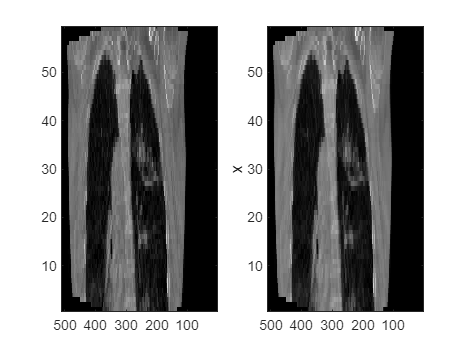

figure()
subplot(1,2,1)
imagesc(squeeze(Scan1(:,200,:)))
view([90 -90])
colormap('gray')
subplot(1,2,2)
imagesc(squeeze(output(:,200,:)))
view([90 -90])
xlabel('x')

% subplot(1,3,3)
% plot(xi)



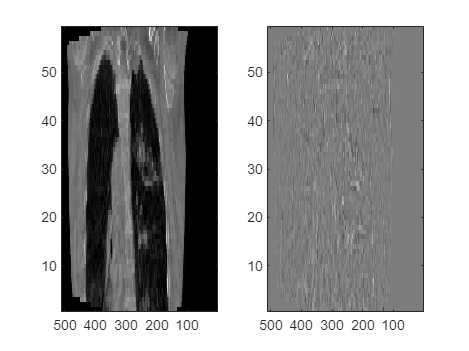

T = Scan1 - output;
imagesc(squeeze(T(:,200,:)))
view([90 -90])
colormap('gray')